Allan Variance Test: Acceleration Data Analysis 

Author: Michael Noyce 

Largely Based on: [https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html](https://www.mathworks.com/help/fusion/ug/inertial-sensor-noise-analysis-using-allan-variance.html) 

**Description**: 

This program performs an Allan Variance Analysis of accelerometer intertial data.  

Note 1: As 3 acceleration Axes are calculated and simulations are performed with the calculated values, this program takes a while if you turn on the simulations! Start it, make a cup of coffee and come back. Only turn on simulations individually if the data needs to be checked. 

Note 2: The x, y and z values for N, K and b should all be very similar (if not the same). I have calculated them for each axis separately as a check that the data is good - if they are quite different, then re-record your data as it may not be good enough (completely stationary IMU for 4hrs or more).

helperAllanVarianceExample.m is needed in the same folder to run simulations with the calculated noise characteristics.  

%Load desired files into a table 
%should be a time series with x, y and z IMU values
%You may need to adjust this part to suit your own data
% '%f' is for each column in the .txt file that contains float number information
IMU_data_table = readtable('9hrsAllanDeviationData.txt','Format','%f%f%f%f%f%f%f%f') %format as floating-point

IMU_data_table = 3264875×8 table
    PacketCounter    SampleTimeFine      Acc_X        Acc_Y      Acc_Z       Gyr_X        Gyr_Y        Gyr_Z  
    _____________    ______________    _________    _________    ______    _________    _________    _________

          1            2.0168e+06      -0.041294     -0.02776    9.7995    -0.000326    -0.002921    -0.002687
          2            2.0169e+06       -0.05629    -0.034893    9.8159    -0.000517    -0.001006     0.000661
          3             2.017e+06      -0.053506    -0.037183    9.8014    -0.000565     0.000217      3.5e-05
          4            2.0171e+06      -0.040233    -0.013471    9.8084     0.003874     0.000467     0.002415
          5            2.017

%Find actual sample rate (Hz) - if your data doesn't have sample time then
%just uncomment the 'fs' variable below and set the sample time manually
sample_time = IMU_data_table{:, 'SampleTimeFine'}; % extract {rows, cols} into an array
record_time = (sample_time(length(sample_time))-sample_time(1))/10000; % length of recording (s)

record_time = 3.2649e+04


samples = IMU_data_table{:, 'PacketCounter'};
num_samples = length(samples);

fs = num_samples/record_time; % sample rate (Hz)
%fs = 100; 
t0 = 1/fs; %sample period

accelX = IMU_data_table{:, 'Acc_X'}; % all rows, Acc_X column
accelY = IMU_data_table{:, 'Acc_Y'};
accelZ = IMU_data_table{:, 'Acc_Z'};

%Integrate accelerometer measurements to find speed 
speedX = cumsum(accelX, 1)*t0; 
speedY = cumsum(accelY, 1)*t0; 
speedZ = cumsum(accelZ, 1)*t0; 

%Simulation Commands (automatically set to false)
%Creates plots using values derived from Allan Variance Tests
%Requires helperAllanVariance.m in same folder
simulateXaxis = false;
simulateYaxis = false;
simulateZaxis = false;

**Acceleration Allan Variance Calculation: X axis **

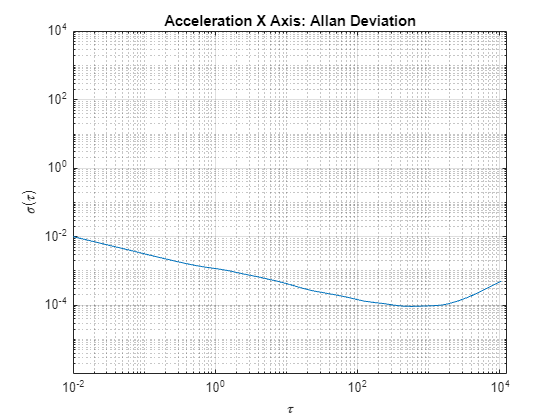

%Allan Variance Calculation: X axis
maxNumM = 100;
L = size(speedX, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.
tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((speedX(1+2*mi:L) - 2*speedX(1+mi:L-mi) + speedX(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev_x = sqrt(avar);

figure
loglog(tau, adev_x)
title('Acceleration X Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


% x-Angle Random Walk Calculation 
% (m/s^2)/sqrt(Hz)

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev_x);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 0.0010

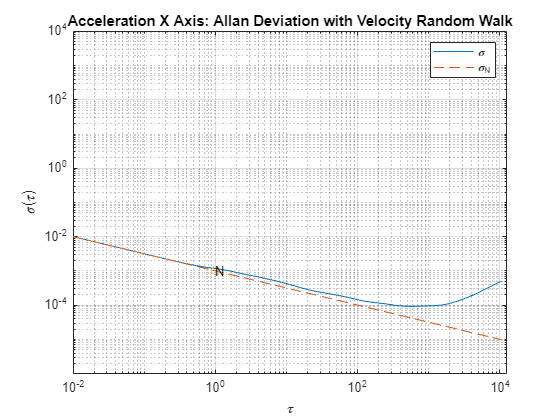


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev_x, tau, lineN, '--', tauN, N, 'o')
title('Acceleration X Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


% x-Rate Random Walk Calulation
% (m/s^3)/sqrt(Hz)

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev_x);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
Kx = 10^logK

Kx = 4.3931e-06

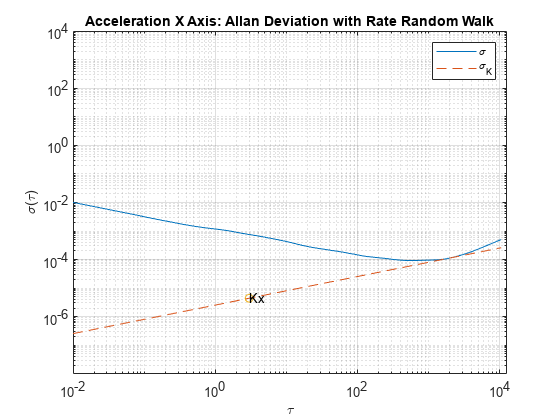


% Plot the results.
tauK = 3;
lineK = Kx .* sqrt(tau/3);
figure
loglog(tau, adev_x, tau, lineK, '--', tauK, Kx, 'o')
title('Acceleration X Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, Kx, 'Kx')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev_x);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 1.3879e-04

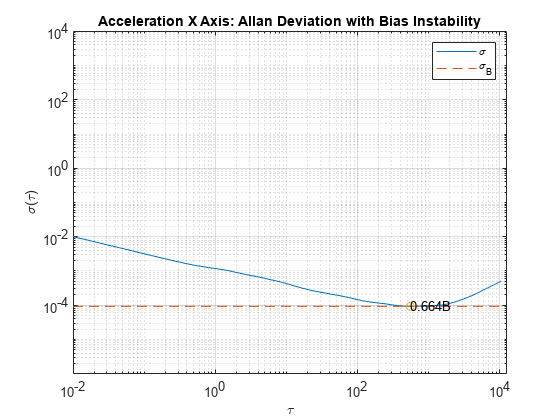


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev_x, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration X Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

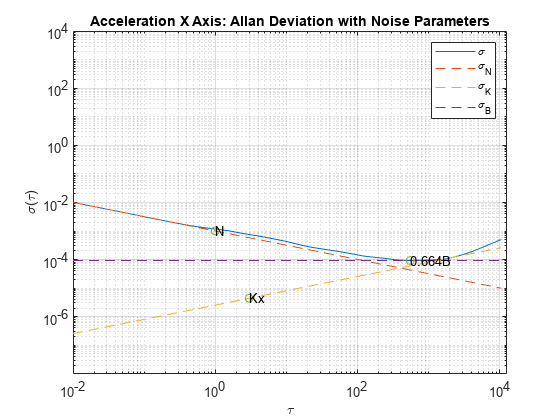


tauParams = [tauN, tauK, tauB];
params = [N, Kx, scfB*B];
figure
loglog(tau, adev_x, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration X Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'Kx', '0.664B'})
grid on
axis equal

**Allan Variance Calculation: Y axis **

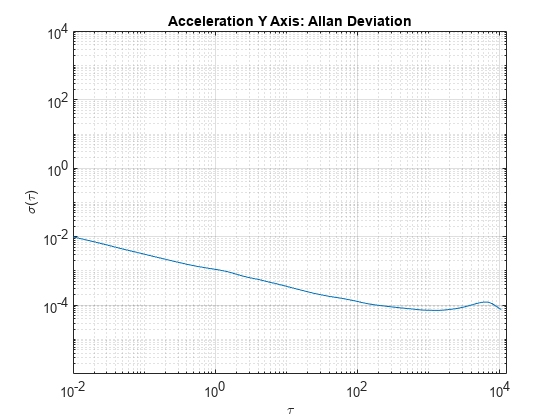

%Allan Variance Calculation: Y axis
maxNumM = 100;
L = size(speedY, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((speedY(1+2*mi:L) - 2*speedY(1+mi:L-mi) + speedY(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev_y = sqrt(avar);

figure
loglog(tau, adev_y)
title('Acceleration Y Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


%Angle Random Walk Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev_y);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 9.7996e-04

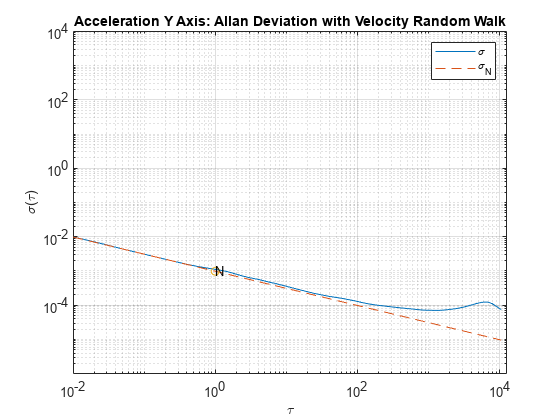


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev_y, tau, lineN, '--', tauN, N, 'o')
title('Acceleration Y Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


%Rate Random Walk Calulation

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev_y);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
Ky = 10^logK

Ky = 2.7311e-06

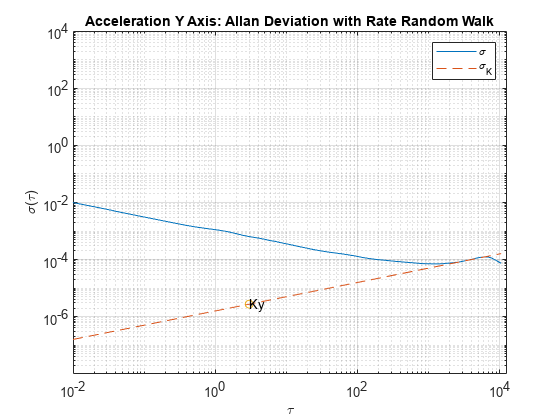


% Plot the results.
tauK = 3;
lineK = Ky .* sqrt(tau/3);
figure
loglog(tau, adev_y, tau, lineK, '--', tauK, Ky, 'o')
title('Acceleration Y Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, Ky, 'Ky')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev_y);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 1.0712e-04

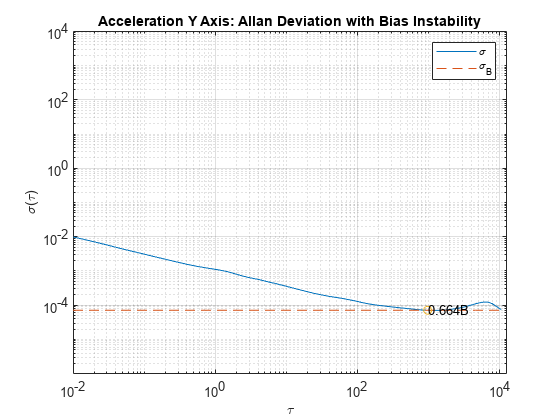


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev_y, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration Y Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

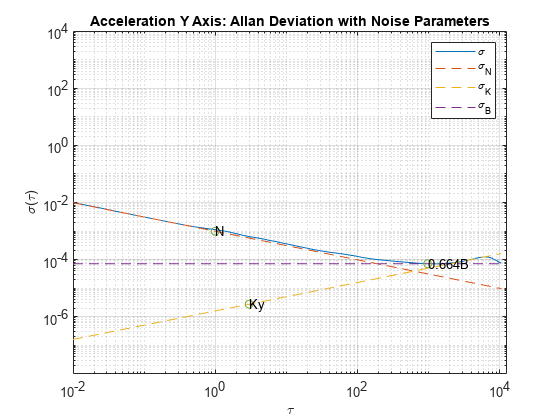

% plot all
tauParams = [tauN, tauK, tauB];
params = [N, Ky, scfB*B];
figure
loglog(tau, adev_y, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration Y Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'Ky', '0.664B'})
grid on
axis equal

**Allan Variance Calculation: Z axis **

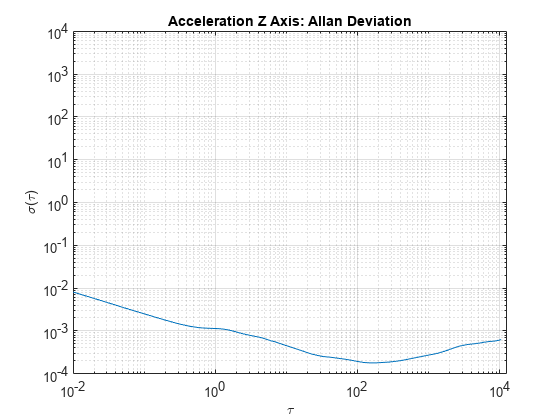

%Allan Variance Calculation: Z axis
maxNumM = 100;
L = size(speedZ, 1);
maxM = 2.^floor(log2(L/2));
m = logspace(log10(1), log10(maxM), maxNumM).';
m = ceil(m); % m must be an integer.
m = unique(m); % Remove duplicates.

tau = m*t0;

avar = zeros(numel(m), 1);
for i = 1:numel(m)
    mi = m(i);
    avar(i,:) = sum((speedZ(1+2*mi:L) - 2*speedZ(1+mi:L-mi) + speedZ(1:L-2*mi)).^2, 1);
end

avar = avar ./ (2*tau.^2 .* (L - 2*m));

adev_z = sqrt(avar);

figure
loglog(tau, adev_z)
title('Acceleration Z Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal


%Angle Random Walk Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = -0.5;
logtau = log10(tau);
logadev = log10(adev_z);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the angle random walk coefficient from the line.
logN = slope*log(1) + b;
N = 10^logN

N = 7.9199e-04

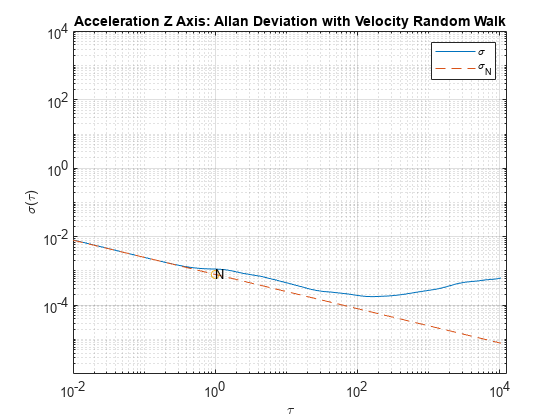


% Plot the results.
tauN = 1;
lineN = N ./ sqrt(tau);
figure
loglog(tau, adev_z, tau, lineN, '--', tauN, N, 'o')
title('Acceleration Z Axis: Allan Deviation with Velocity Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N')
text(tauN, N, 'N')
grid on
axis equal


%Rate Random Walk Calulation

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0.5;
logtau = log10(tau);
logadev = log10(adev_z);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the rate random walk coefficient from the line.
logK = slope*log10(3) + b;
Kz = 10^logK

Kz = 1.4092e-05

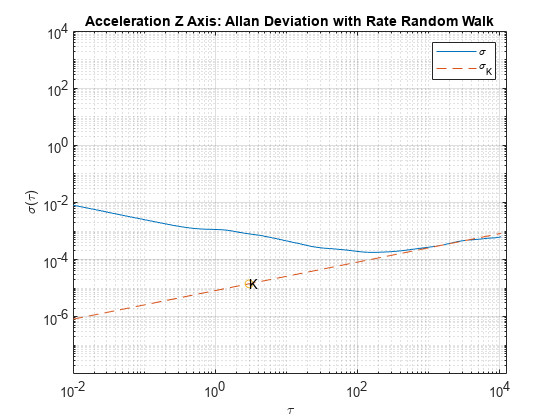


% Plot the results.
tauK = 3;
lineK = Kz .* sqrt(tau/3);
figure
loglog(tau, adev_z, tau, lineK, '--', tauK, Kz, 'o')
title('Acceleration Z Axis: Allan Deviation with Rate Random Walk')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_K')
text(tauK, Kz, 'K')
grid on
axis equal


%Bias Instability Calculation 

% Find the index where the slope of the log-scaled Allan deviation is equal
% to the slope specified.
slope = 0;
logtau = log10(tau);
logadev = log10(adev_z);
dlogadev = diff(logadev) ./ diff(logtau);
[~, i] = min(abs(dlogadev - slope));

% Find the y-intercept of the line.
b = logadev(i) - slope*logtau(i);

% Determine the bias instability coefficient from the line.
scfB = sqrt(2*log(2)/pi);
logB = b - log10(scfB);
B = 10^logB

B = 2.6817e-04

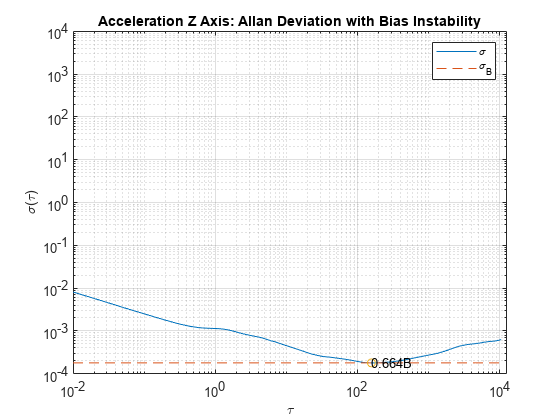


% Plot the results.
tauB = tau(i);
lineB = B * scfB * ones(size(tau));
figure
loglog(tau, adev_z, tau, lineB, '--', tauB, scfB*B, 'o')
title('Acceleration Z Axis: Allan Deviation with Bias Instability')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_B')
text(tauB, scfB*B, '0.664B')
grid on
axis equal

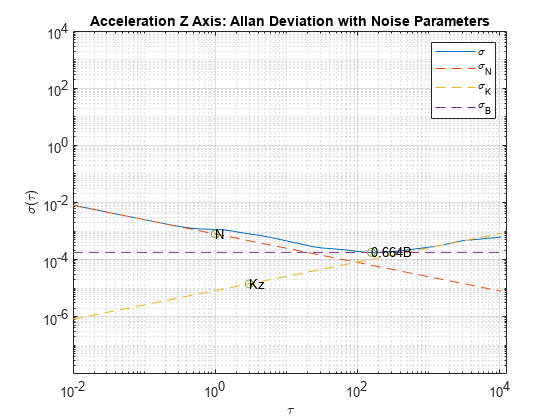

% plot all
tauParams = [tauN, tauK, tauB];
params = [N, Kz, scfB*B];
figure
loglog(tau, adev_z, tau, [lineN, lineK, lineB], '--', ...
    tauParams, params, 'o')
title('Acceleration Z Axis: Allan Deviation with Noise Parameters')
xlabel('\tau')
ylabel('\sigma(\tau)')
legend('\sigma', '\sigma_N', '\sigma_K', '\sigma_B')
text(tauParams, params, {'N', 'Kz', '0.664B'})
grid on
axis equal

**Combined X, Y, Z Graph**

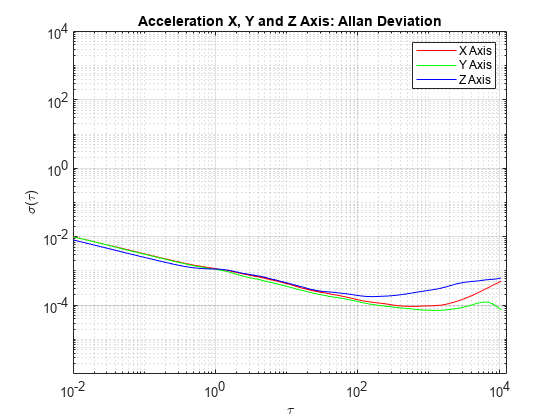

figure
loglog(tau, adev_x, 'red', tau, adev_y, 'green', tau, adev_z, 'blue')
title('Acceleration X, Y and Z Axis: Allan Deviation')
xlabel('\tau');
ylabel('\sigma(\tau)')
grid on
axis equal
legend('X Axis', 'Y Axis', 'Z Axis')